# Stokes boundary conditions

clear, clc
set_demo_defaults()

When solving the Stokes equation we have three separate unknowns, vx, vy and p located at three different places. This can lead to confusion when assigning the boundary conditions, in particular to the same unkown twice. If `solve_lbvp.m` tells you your reduced matrix is not invertible, most likely you have over-specified the boundary conditions.

For the problems we will encounter in this class we want to specify four different types of boundary conditions:

- **No penetration:** The normal component of the fluid along the boundary is zero. (Dirichlet)

- **Prescribed slip:** The tangential component of the velocity along the boundary is prescribed. (Dirichlet)

- **Free slip/no shear stress:** The normal derivative of the tangential velocity is zero. (Hom. Neumann/Natural)

- **Pressure constraint:** We need to set a scale for the pressure because it has homogeous Neuman BC's.

The Free Slip boundary condition is the natural boundary condition on the velocity, so we do not have to impose it.

Lets look at a typical grid and the distribution of our unknowns.

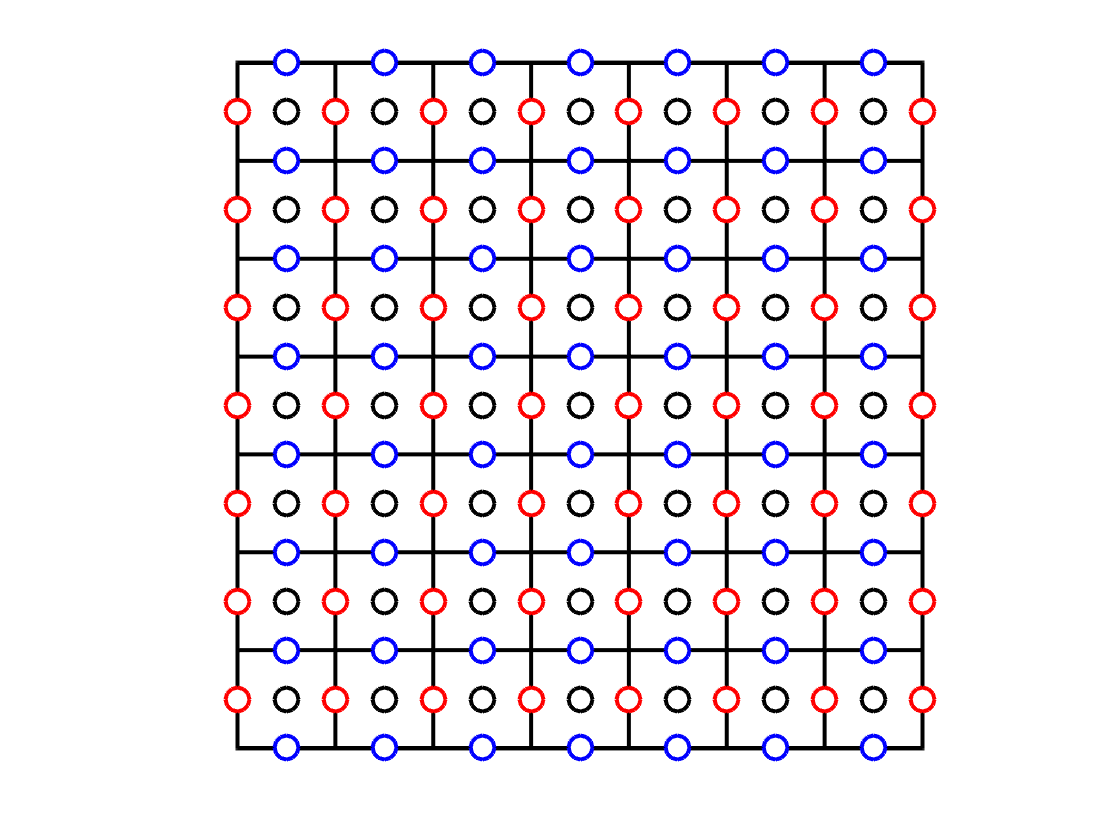

Gridp.xmin = 0; Gridp.xmax = 1; Gridp.Nx = 7;
Gridp.ymin = 0; Gridp.ymax = 1; Gridp.Ny = 7;
Grid = build_stokes_grid(Gridp);
x = Grid.p.xf; y = Grid.p.yf; Nx = Grid.p.Nx+1; Ny = Grid.p.Ny+1;
[Xc,Yc] = meshgrid(Grid.p.xc,Grid.p.yc);
[Xx,Yx] = meshgrid(Grid.x.xc,Grid.x.yc);
[Xy,Yy] = meshgrid(Grid.y.xc,Grid.y.yc);
X = [Xx(:);Xy(:);Xc(:)];
Y = [Yx(:);Yy(:);Yc(:)];
fig1 = plot_staggered_grid(Grid.p);
axis equal tight
set(gca,'xtick',[],'ytick',[])

The first task is to identify the dof's of each variable associated with each face. All of this can be done referring only to the dof vectors of the primary grid, because that contains cell centers in `dof` and the velocities on the faces in `dof_f`. The dof vectors we generate for the Stokes system should refer to the position of an unknown in the total vector of unknowns, `u = [vx,vy,p]'`. Hence to identify `p` in **u** we need to add `Nf` to `dof`, because **p** is stored after the velocities. Hence we will add the following 12 vectors to grid:

- For pressure: `dof_xmin_p`, `dof_xmax_p`, `dof_ymin_p`, `dof_ymax_p`

- For x-velocity: `dof_xmin_vx`, `dof_xmax_vx`, `dof_ymin_vx`, `dof_ymax_vy`

- For y-velocity: `dof_xmin_vy`, `dof_xmax_vy`, `dof_ymin_vy`, `dof_ymax_vy`

These arrays are sufficient to specify the BC, but it is repetitive and renders the top level code unreadable. Hence, we will pre-define additional dof vectors for commonly used boundary conditions. But first let's visualize   

We can visualize the pressures on the x-min boundary

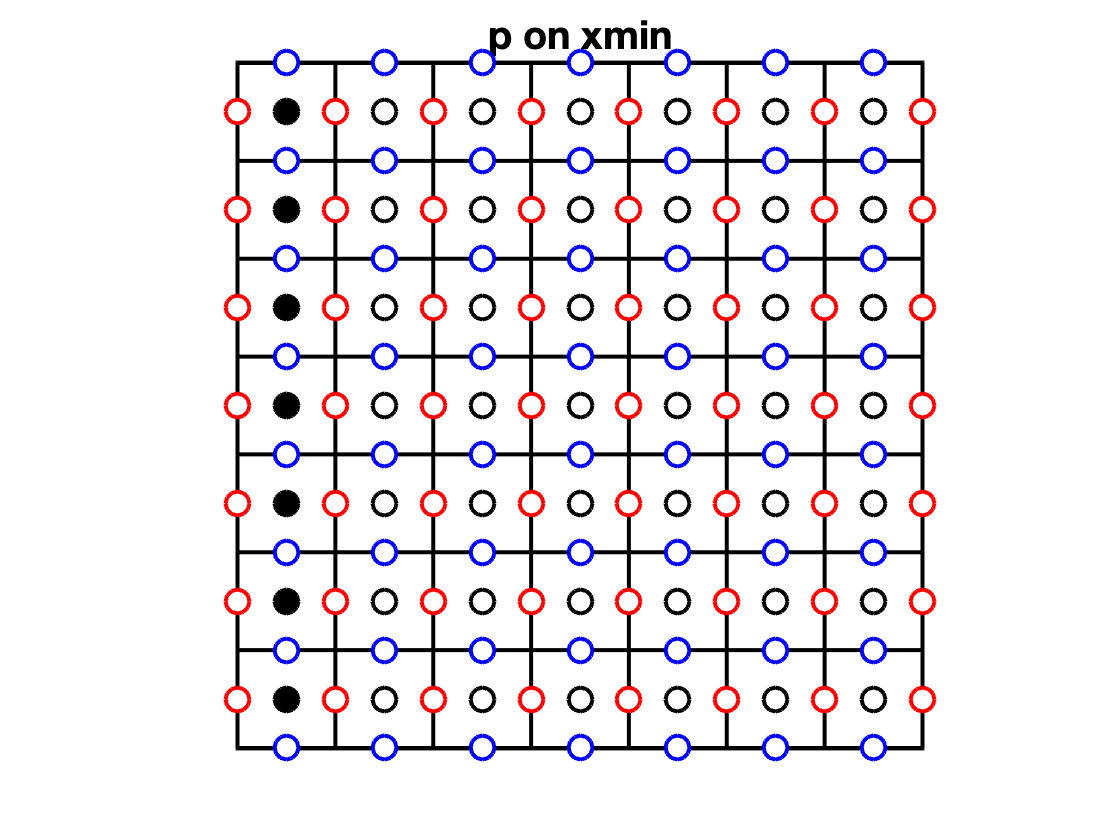

plot_staggered_grid(Grid.p);
plot(X(Grid.dof_xmin_p),Y(Grid.dof_xmin_p),'ko','markerfacecolor','k')
axis equal tight
set(gca,'xtick',[],'ytick',[])
title 'p on xmin'

We can visualize the x-velocities on the x-max boundary

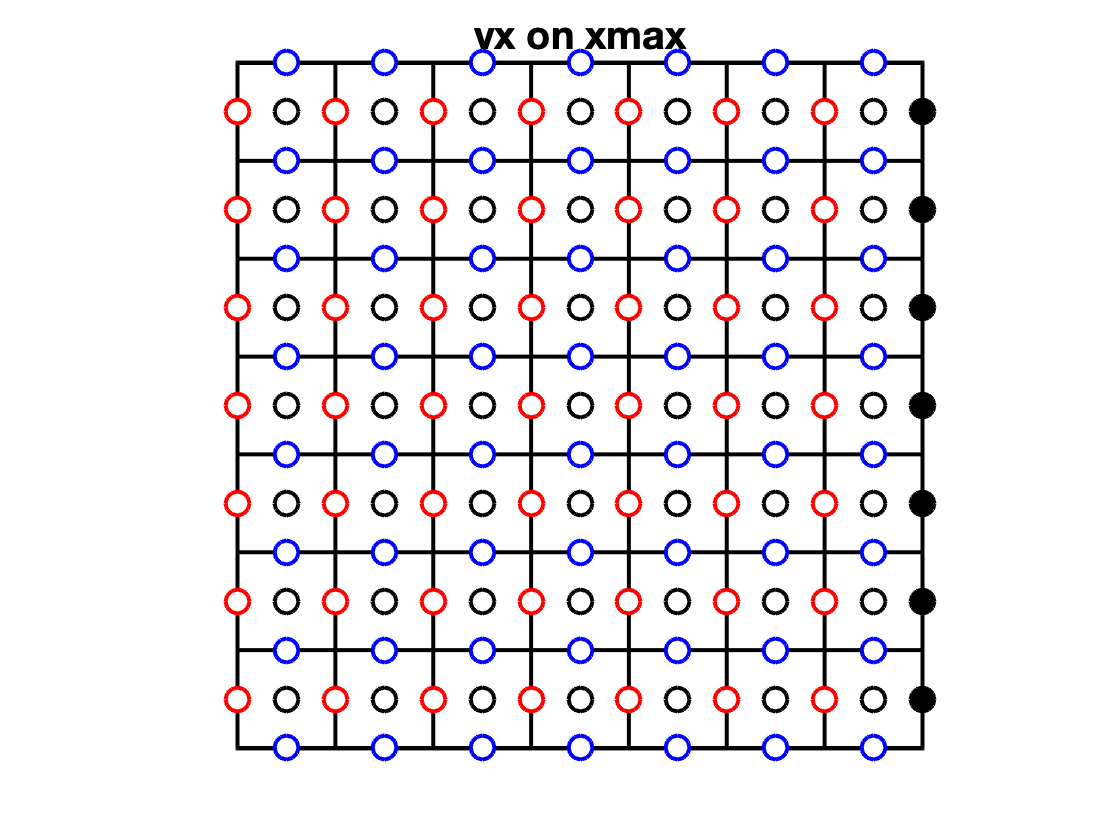

plot_staggered_grid(Grid.p);
plot(X(Grid.dof_xmax_vx),Y(Grid.dof_xmax_vx),'ko','markerfacecolor','k')
axis equal tight
set(gca,'xtick',[],'ytick',[])
title 'vx on xmax'

We can visualize the x-velocities on the y-max boundary

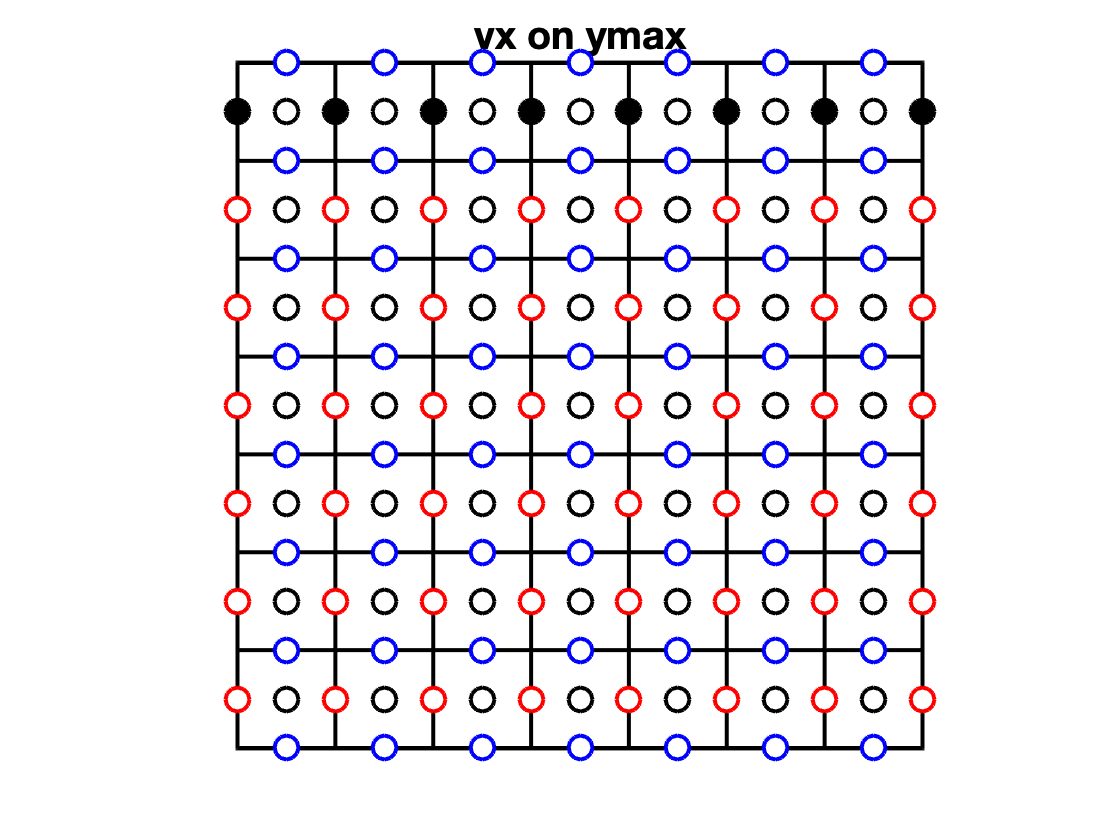

plot_staggered_grid(Grid.p);
plot(X(Grid.dof_ymax_vx),Y(Grid.dof_ymax_vx),'ko','markerfacecolor','k')
axis equal tight
set(gca,'xtick',[],'ytick',[])
title 'vx on ymax'

Note that the x-velocity on the top right face is included on both the `Grid.dof_ymax_vx` and the `Grid.dof_xmax_vx` vectors. This can lead to over specification and matrices that are not invertible. Hence, we define additional vectors below to simplify the specification of boundary conditions and avoid this.

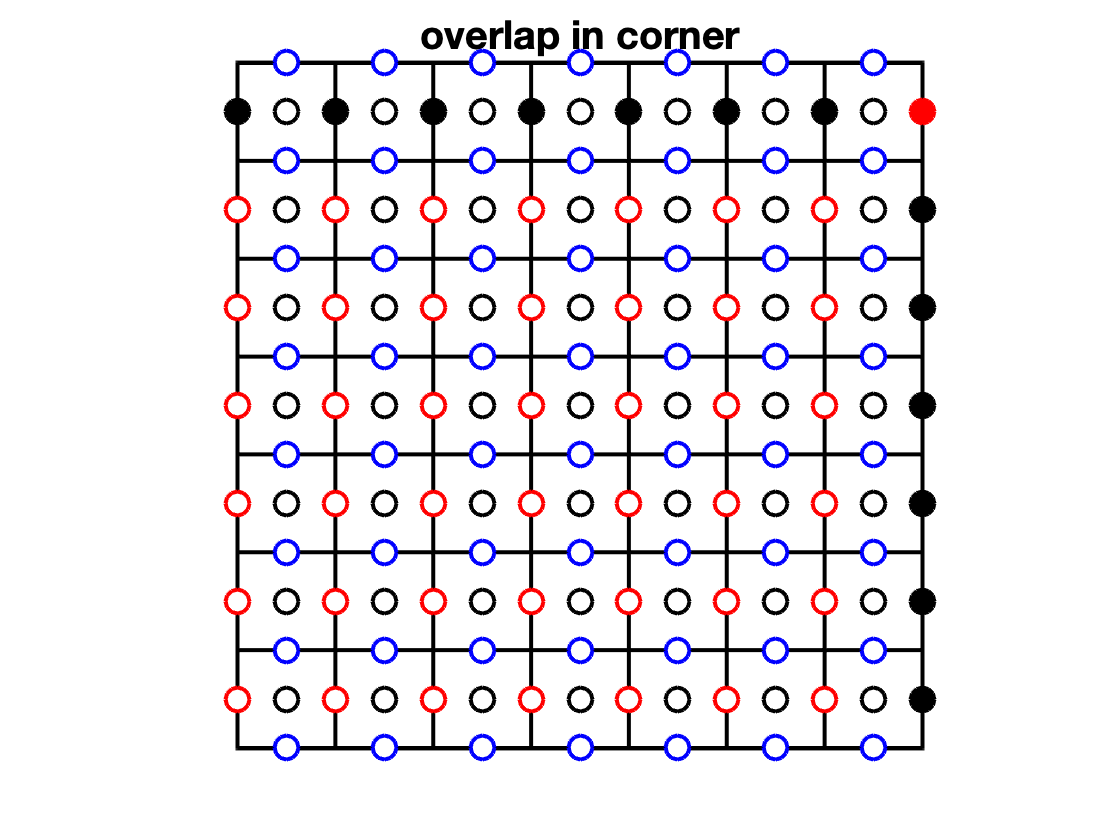

plot_staggered_grid(Grid.p);
plot(X(Grid.dof_ymax_vx),Y(Grid.dof_ymax_vx),'ko','markerfacecolor','k')
plot(X(Grid.dof_xmax_vx),Y(Grid.dof_xmax_vx),'ko','markerfacecolor','k')
plot(X(Grid.dof_ymax_vx(end)),Y(Grid.dof_ymax_vx(end)),'ro','markerfacecolor','r')
axis equal tight
set(gca,'xtick',[],'ytick',[])
title 'overlap in corner'

## Total penetration BC's

Since all of our problems are in closed domains we add a new vector to `Grid` that contains all normal velocities, `Grid.dof_pene`.

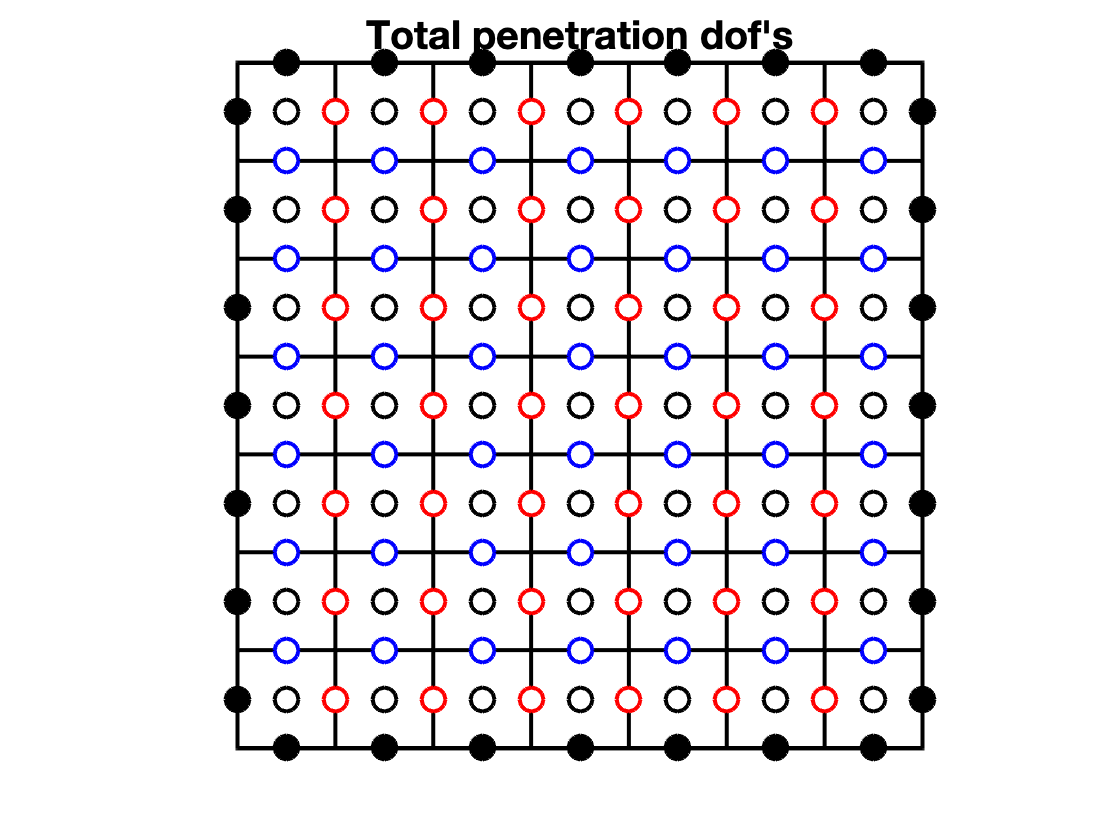

plot_staggered_grid(Grid.p);
plot(X(Grid.dof_pene),Y(Grid.dof_pene),'ko','markerfacecolor','k')
axis equal tight
set(gca,'xtick',[],'ytick',[])
title 'Total penetration dof''s'

To help specify the BC.g vector we also store the total number of dof's in this vector

Grid.N_pene

ans = 28

## **Slip BC's**

To specify the tangential velocities along a face we need to exclude the the two end faces, because those may be independetly set by penetration BC's. While this is a simple change we will define 4 new vectors that simplify the specification of slip boundary conditions:

- Slip boundaries: `dof_xmin_vt`, `dof_xmax_vt`, `dof_ymin_vt`, `dof_ymax_vx`

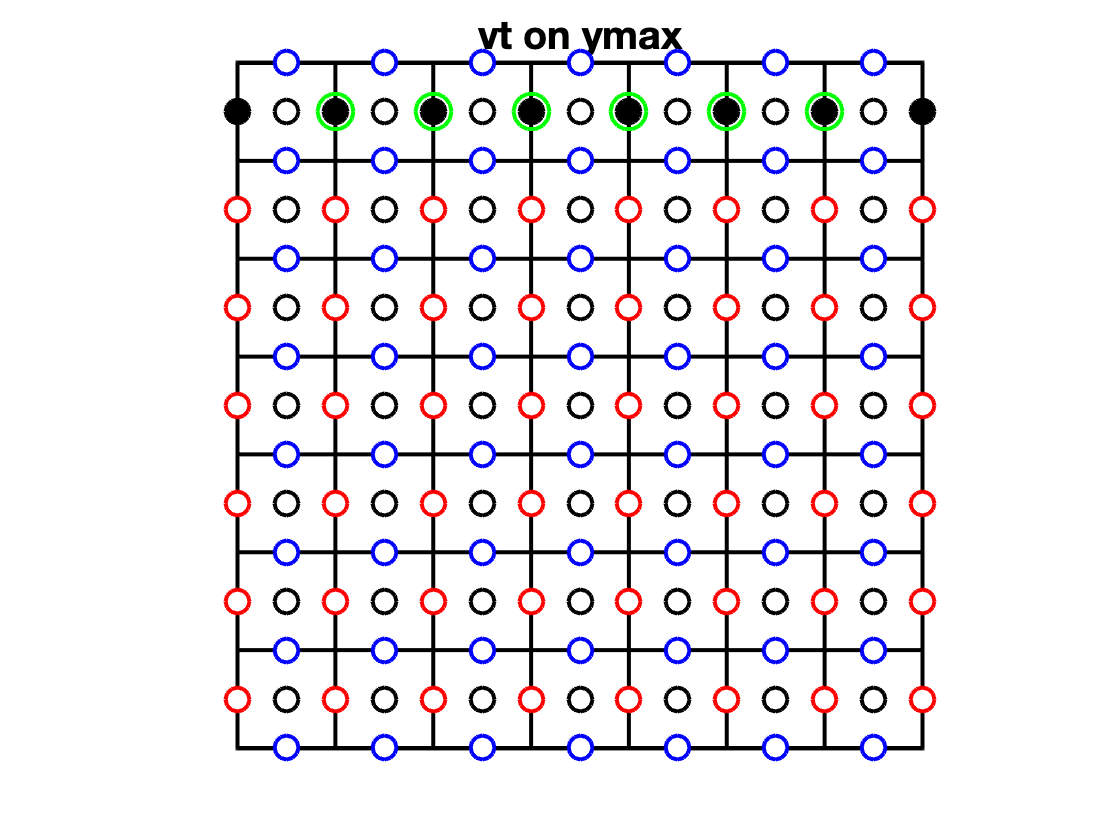

plot_staggered_grid(Grid.p);
plot(X(Grid.dof_ymax_vx),Y(Grid.dof_ymax_vx),'ko','markerfacecolor','k')
plot(X(Grid.dof_ymax_vt),Y(Grid.dof_ymax_vt),'ko','markerfacecolor','none','markeredgecolor','g','markersize',18)
axis equal tight
set(gca,'xtick',[],'ytick',[])
title 'vt on ymax'

## Total slip BC's

Because we often specify no slip on all bnd's we add an additional vector of all tangential components

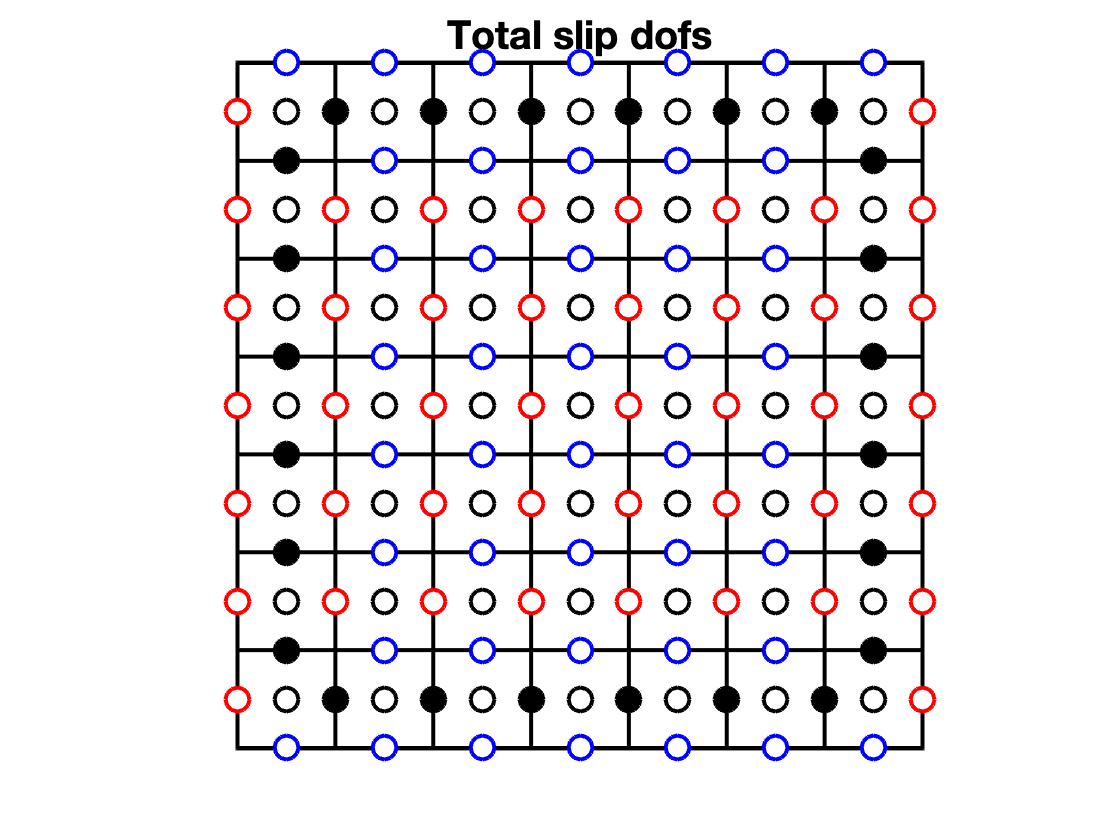

plot_staggered_grid(Grid.p);
plot(X(Grid.dof_slip),Y(Grid.dof_slip),'ko','markerfacecolor','k')
axis equal tight
set(gca,'xtick',[],'ytick',[])
title 'Total slip dof's

Along solid boundaries we typically have a no-slip boundary condition so we need to specify all tangential velocities on all faces. To define 